## TOPIC 25: Animations

ENGR105, 11/30/20

#### Reminder: animating simple graphical objects

So far, we have produced visualizations and simulations involving the movement of simple **graphics handle objects**, such as **circles** and **squares**. For example, in Topic 20 we produced a particle-based simulation to represent the spread of infectious disease. The code for this is shown here.

*Key features:*

- The objects that are moving are declared as **graphics handle objects**. The position and color of each is updated by changing the appropriate **fields** of the **handle**.

- The order of the code is important. In this case, it is important to first create the "background." That is, it is important to first create the axes, set the limits, etc. **In other cases, you may need to create an object first**. A useful troubleshooting approach is think about the order in which you create things.

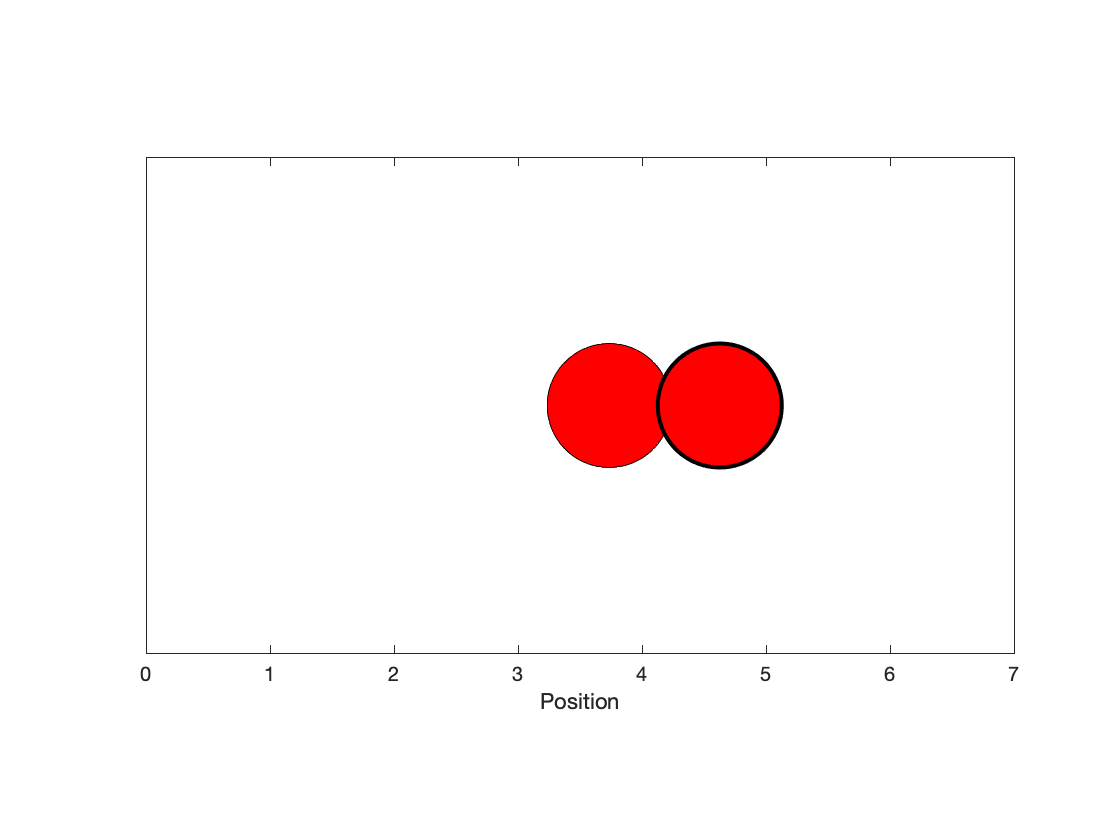

close all

% 1) Vector representing positions of two particles
pos = [1,4];

% 2) Define particle identities.
% Particle 1 will be infected
% Particle 2 will initially be healthy

% 3) Produce visualization of each particle
g1 = axes;
axis image              % Setting this ensures that the x and y scales are equal on the resulting image
xlim([0,7])             % X limits
ylim([-2,2])            % Y limits
set(g1,'ytick',[])      % Turn off y tick marks
set(g1,'Box','on')
xlabel('Position')      % X label

% Plot both particles initial position
p1 = rectangle('Position',[pos(1),-0.5,1,1],'Curvature',[1,1],'FaceColor','r');
p2 = rectangle('Position',[pos(2),-0.5,1,1],'Curvature',[1,1],'FaceColor','w','LineWidth',2);

% Step through the simulation. In each step, update the particles positions
while abs(pos(1)-pos(2)) >= 1

    % A) Create vector determining particle step
    d_k = (rand(1,2)-0.5);
    
    % B) Update particle position
    pos = pos + d_k;
    
    % C) Ensure particle doesn't move out of bounds
    pos = max(min(pos,6),0);
    
    % If difference between particles is less than one diameter, an
    % infection has occurred
    if abs(pos(1)-pos(2)) < 1
        p2.FaceColor = 'r';
    end
    
    % D) Update visualization
    p1.Position(1) = pos(1);
    p2.Position(1) = pos(2);
    
    % E) Pause MATLAB
    pause(0.2)
end

Thoughts on creating more sophisticated objects from combinations of objects:

- It is possible to group objects together.

- However, remember that a graphics handle object (whether an individual or group) can only be modified by changing *fields* of the handle object. When in doubt, use `get()` to retrieve possible fields to change.

- If a field is not available (e.g. for a group), you will need to change the desired field for each of the individual objects.

**Takeaway**: use `get()` to help troubleshoot possible modifications to an object.

#### Reminder: the flow of information in an interface

Furthermore, remember that consideration must be put into *how* information is transferred between objects and functions within an interface object. 

***Graphics objects we've discussed so far:***

- `figure` objects

- `axes` objects

- `plot`/`bar`/(data visualization) objects

- `rectangle` objects

- `uicontrol` objects

- `text` objects

- `legend` objects

- `ylabel, xlabel, title, xlim, ylim` objects

- Others?

- **Rule of thumb**: *if it creates something visual on a graph, plot, figure window, etc., then it can be stored and modified as a graphics handle object.*

**Interfaces are based on a **`figure`** object.** **The figure is the parent** that *contains* axes, uicontrols, text, callback functions, etc.

**Example**. updating a "score" counter

- **Rule of thumb: **wherever you pass a callback function (*e.g.* mouse, keyboard, uicontrol, timer, etc.), you can specify additional arguments by passing a cell array that contains the function and additional inputs, e.g. with `{}`.

**Note**: this example uses `uicontrols`, which we discussed in Topic 21 / Lecture 22.

% Initialize the figure/gui window and center
ss = get(0,'ScreenSize');
fig = figure('Visible','on','Position',ss.*.5);
movegui(fig,'center')

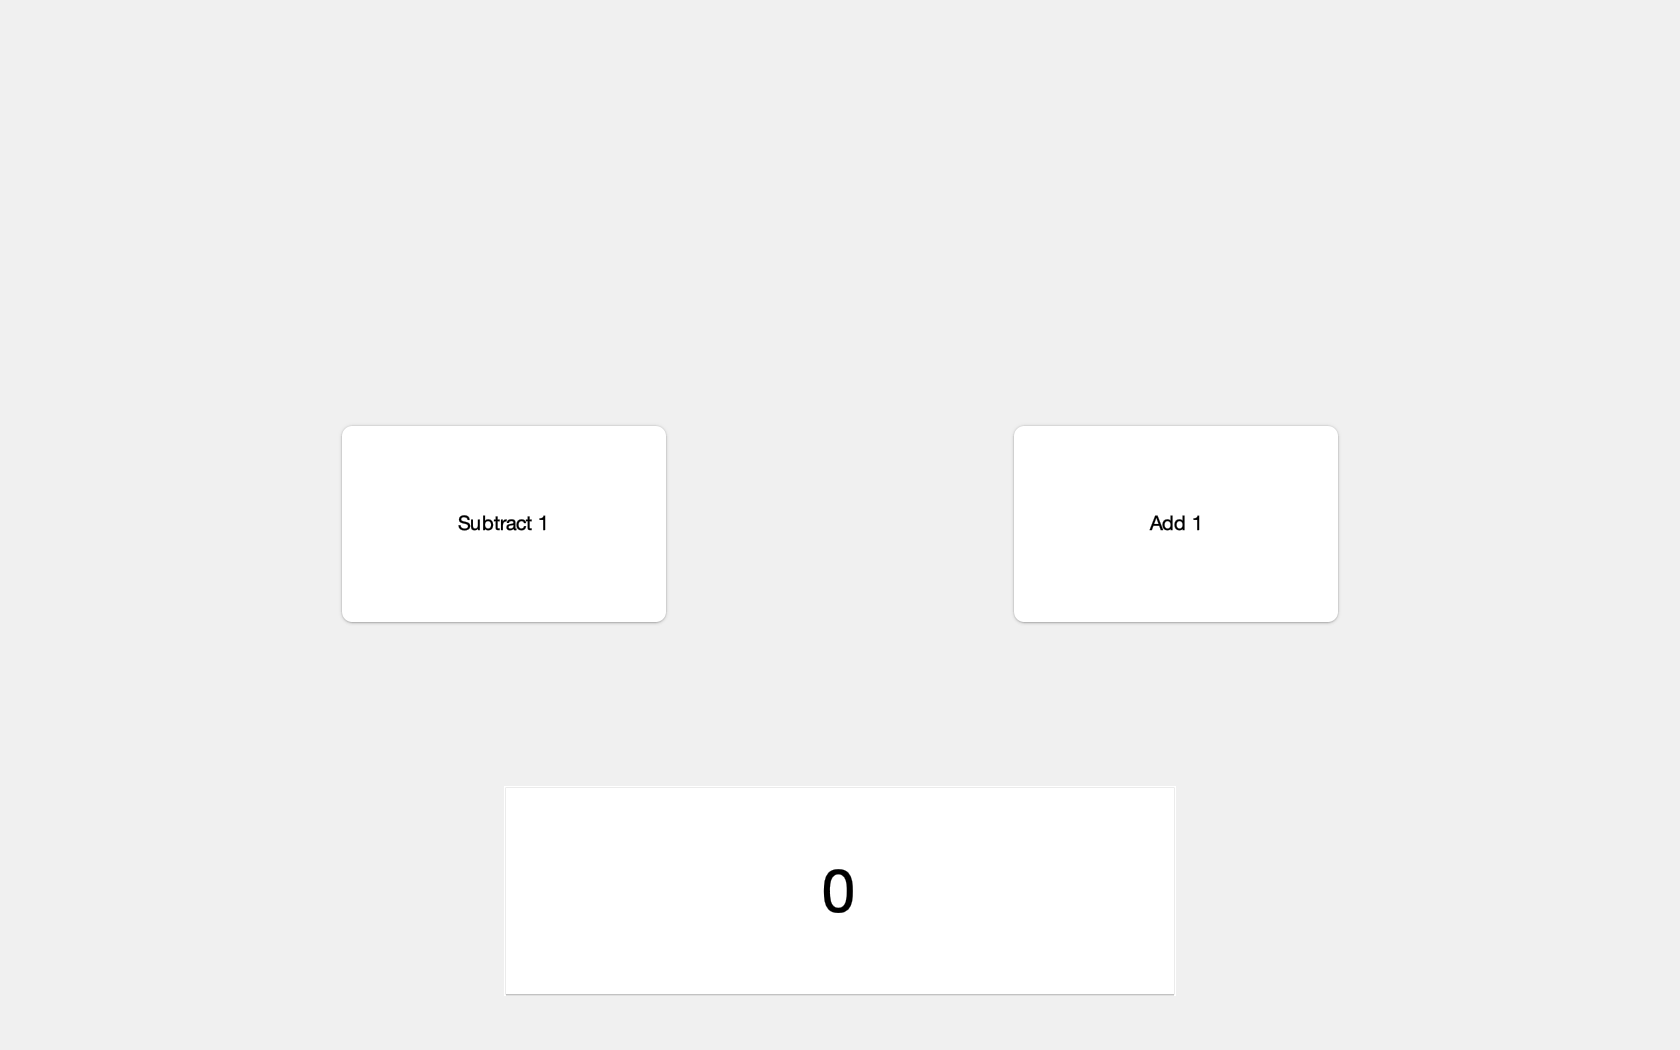


% Initialize the counter value
cVal = 0;

% Add an "edit text" box to show the current value of the counter
hedit = uicontrol('Style','edit','Units','Normalized','Position',...
    [0.3 0.05 0.4 0.2],'FontSize',30,'String',cVal);

% Pushbutton to subtract 1 from the current value of the counter
uicontrol('Style','pushbutton','Units','Normalized','Position',...
    [0.2 0.4 0.2 0.2],'String','Subtract 1','Callback',{@subtractVal,cVal,hedit});

% Pushbutton to add 1 to the current value of the counter
uicontrol('Style','pushbutton','Units','Normalized','Position',...
    [0.6 0.4 0.2 0.2],'String','Add 1','Callback',{@addVal,cVal,hedit});

**Issue**: information is passed to the appropriate objects, but the counter is not actually stored anywhere. Remember, what happens in a function, stays in a function (unless otherwise appropriately passed).

**Workaround: **`guidata`

- Remember that guidata can be used to store a data structure associated with a parent figure (interface).

- This data structure should be initially stored in your script, then loaded and restored inside each function.

- Storing `guidata`:

- Loading `guidata` inside a function:

### Animations

Whether you are designing a simulation, interactive visualization, or game, you may want to incorporate (and **animate**) more sophisticated objects than simply square, rectangles, or circles. To incorporate more sophisticated objects, you could:

- Draw them from square, circles, lines, etc. in MATLAB

- **Import images** into the plot space. We will focus on this here.

#### Revisiting image processing

Recall from before:

- **images are just "integer matrices," ** in which the each index corresponds to a unique **pixel**, and the value of the corresponding element is the **gray value** of that pixel. 

- The bit depth of an image corresponds to the range of possible integer values each element can take. Color images are 3D matrices.

- An image **may be read into MATLAB** using the `imread` function.

- An image may be **displayed** using `imshow`

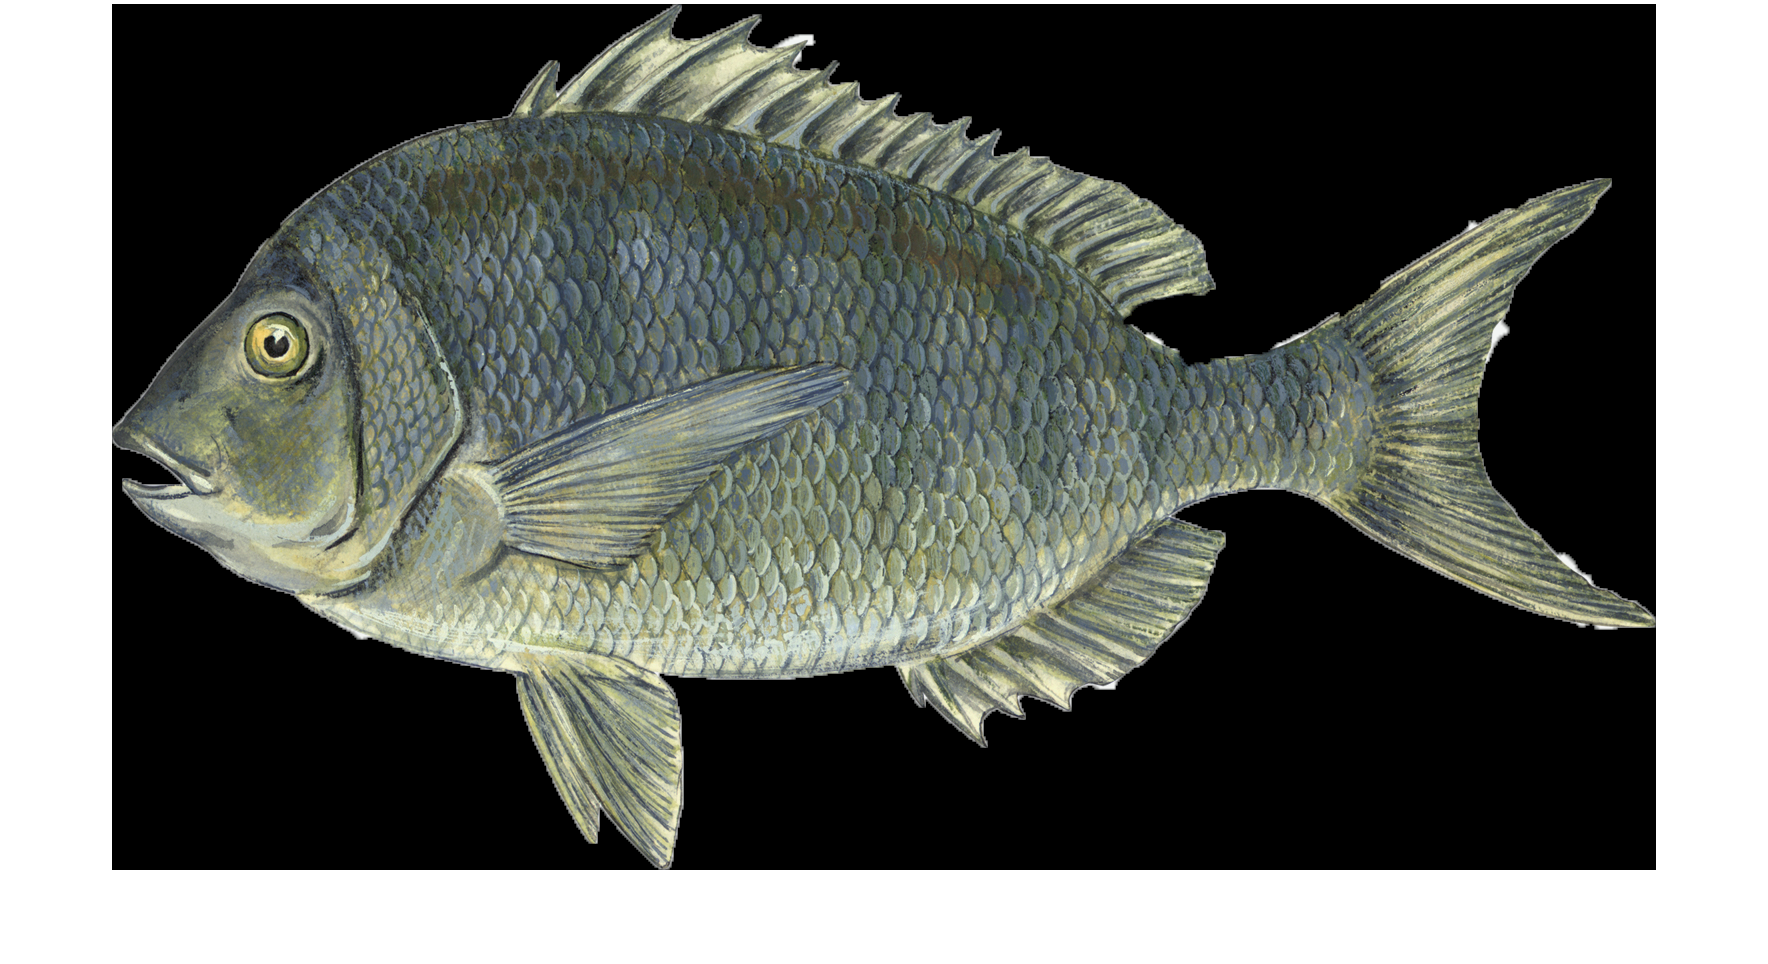

close all
fishPic = imread('fish.png');
imshow(fishPic)

*Source: the above image is of a Porgy fish, courtesy of the Encyclopedia Britannica.*

% A color image is a 3D matrix
size(fishPic)

ans =          866        1544           3


#### Images as graphical handles objects

In general, all visualizations can be stored as graphics handle objects. Images are no different and may be placed in precise **positions** on a pair of axes and **stretched** by modifying the `xData` and `yData `properties.

*In the following example, we:*

- **Create a graphics handle object **corresponding to the fish.

- **Scale the object's size** by changing the `XData` and `YData` fields.

close all

% Create figure and axes that are visible
ss = get(0,'ScreenSize');
h1 = figure('Visible','on','Position',ss.*.5);
g1 = axes;

% Create graphics handle object describing fish
hFish = imshow(fishPic)

hFish =   Image with properties:

           CData: [866×1544×3 uint8]
    CDataMapping: 'direct'

  Show all properties


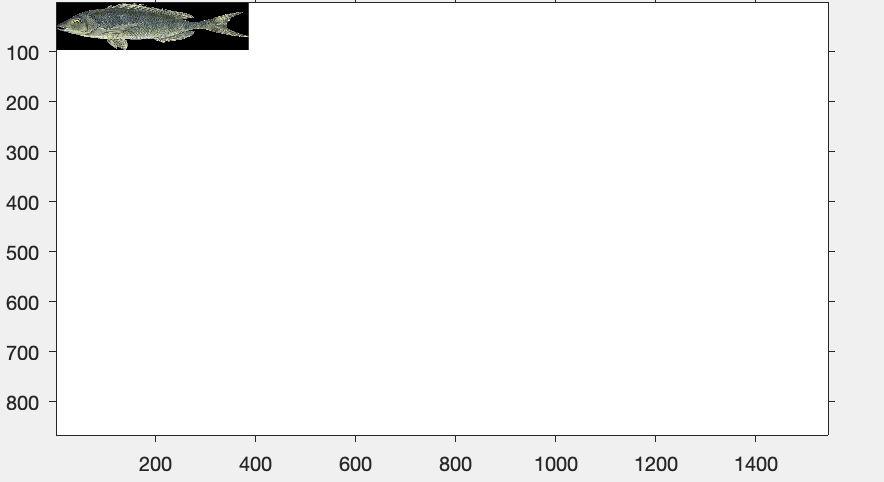


% Define scaling factor
sf = 0.25;

% Change scaling of image on axes
hFish.XData = [1,sf*hFish.XData(2)];
hFish.YData = [1,sf*hFish.XData(2)];

% Ensure axes are visible
g1.Visible = 'on';

% Reduce figure window size
h1.Position(3:4) = 0.5*h1.Position(3:4);

**Note**: the units of the above plot are pixels. By definition, the upper left corner is the origin at (0,0)

Furthermore, we can change the **position** of fish by translating the values in the XData and YData fields of the fish object.

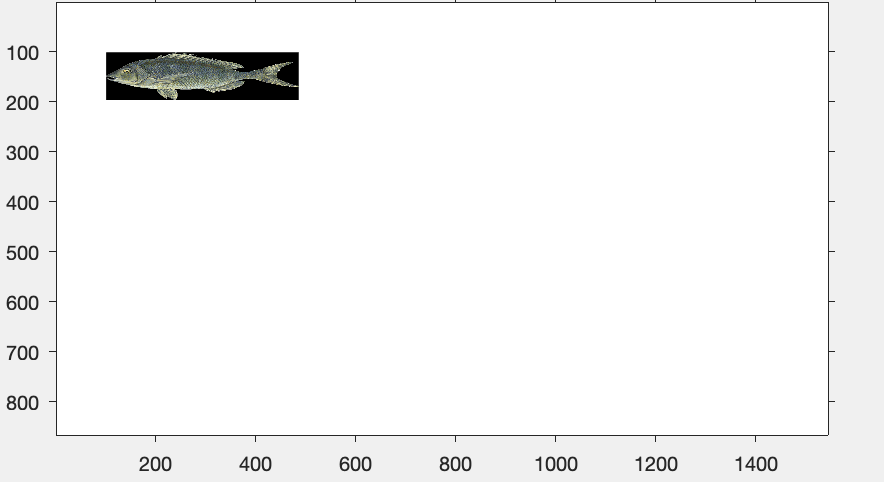

% Move the object away from the origin
hFish.XData = hFish.XData + 100;
hFish.YData = hFish.YData + 100;

**Note**: `XData` and `YData` are two element vectors and contain the X and Y "extent" of an object. If the entries in one vector are **reversed**, the object is reversed.

- A simple way to do this is with array manipulation commands, e.g. `fliplr`

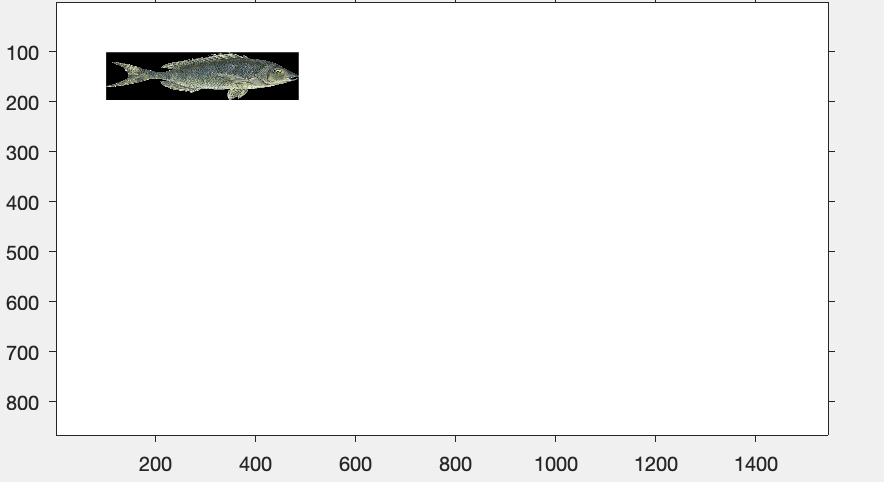

% Flip the orientation of the object
hFish.XData = fliplr(hFish.XData);

#### Image transparency

Consider the above fish object. Say we want to create a visualization of fish in blue water by changing the background color of the axes object.

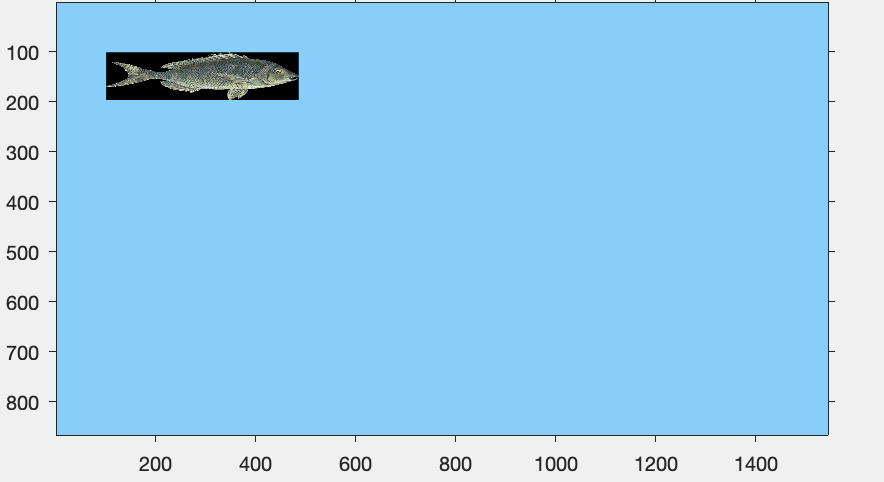

% Change the axes background to blue
g1.Color = [135,206,250]/255;

**Issue**: the black background of the fish object disrupts the overall visualization.

Fortunately, `.png`** images often contain transparency data** (`alphaData`) that can be read as the third output argument from `imread``().`

- An `AlphaData` value of 0 represents a fully transparent pixel and an `AlphaData` value of 255 indicates an opaque (fully visible) pixel – values in between indicate a semi-transparent pixel.

- Typically, jpg, jpeg, bmp, and tif image formats do not support transparency – only png image type.

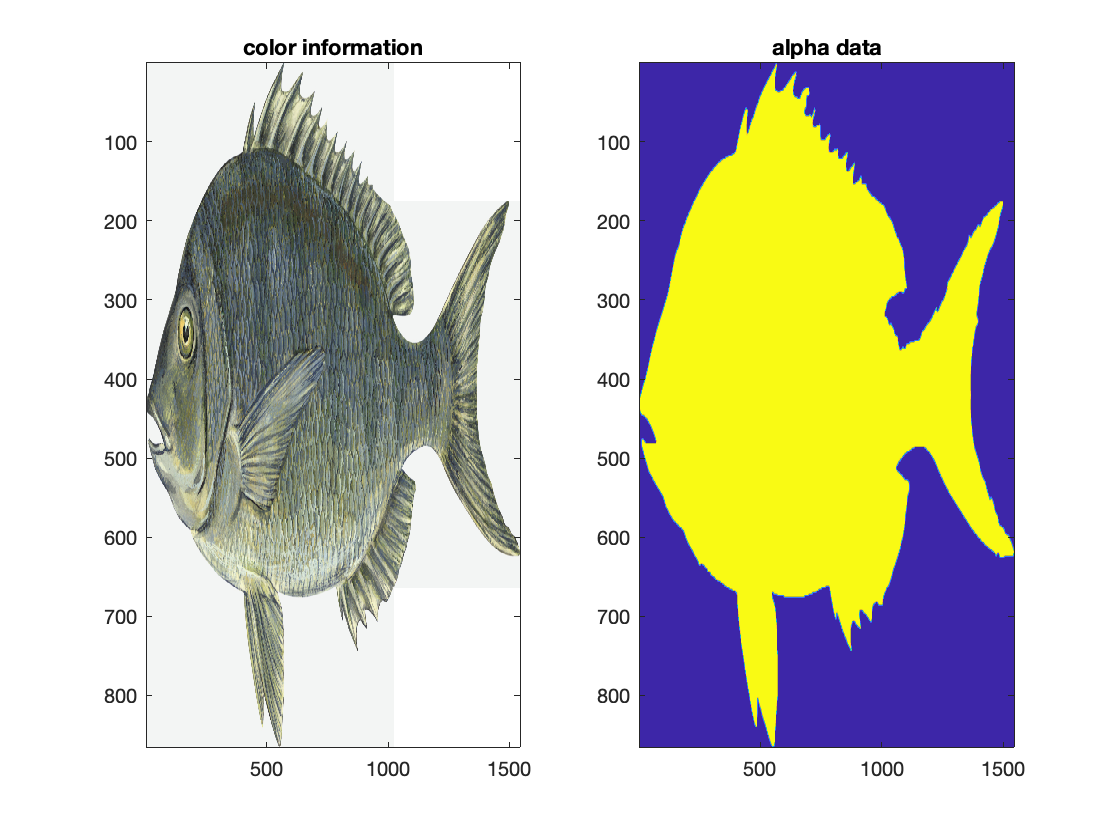

close all

% Read the fish picture and associated alpha data
[fishPic,~,alphaFish] = imread('fish.png');

subplot(1,2,1)
image(fishPic)
title('color information')

subplot(1,2,2)
image(alphaFish)
title('alpha data')

The transparency information in `.png` images may be used to remove image backgrounds and overlap images without the interference from background borders.

- The following code incorporates this tranparency information.

- The `AlphaData` field in a graphics handle object associated with an image can be used to specify the alpha data

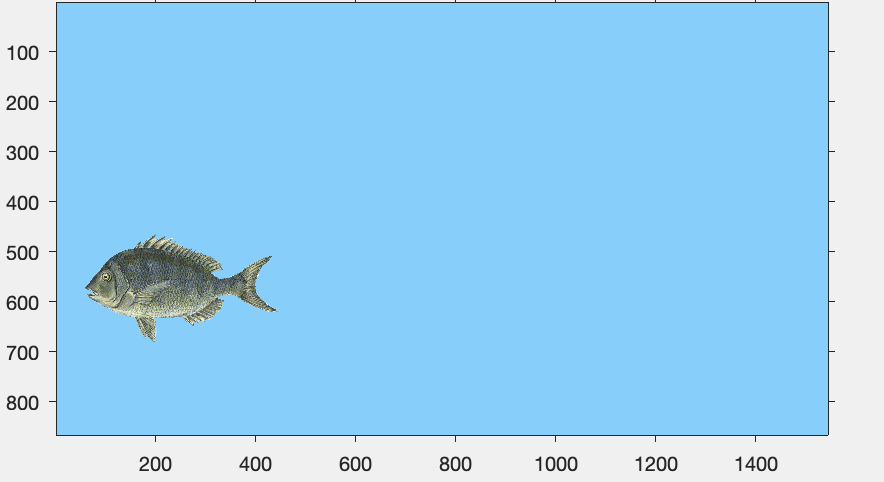

close all

% Create figure and axes that are visible
h1 = figure('Visible','on');
g1 = axes;

% Create graphics handle object describing fish
hFish(1) = imshow(fishPic);

% Assign alpha data
hFish(1).AlphaData = alphaFish;

% Define scaling factor
sf = 0.25;

% Change scaling of image on axes
hFish(1).XData = [1,sf*hFish(1).XData(2)]+randi(500);
hFish(1).YData = [1,sf*hFish(1).YData(2)]+randi(500);

% Ensure axes are visible
g1.Visible = 'on';

% Reduce figure window size
h1.Position(3:4) = 0.5*h1.Position(3:4);

% Change the axes background to blue
g1.Color = [135,206,250]/255;

**Adding more fish to the image.** Since the only the region specified by the alpha data is depicted, you can potentially overlap many fish.

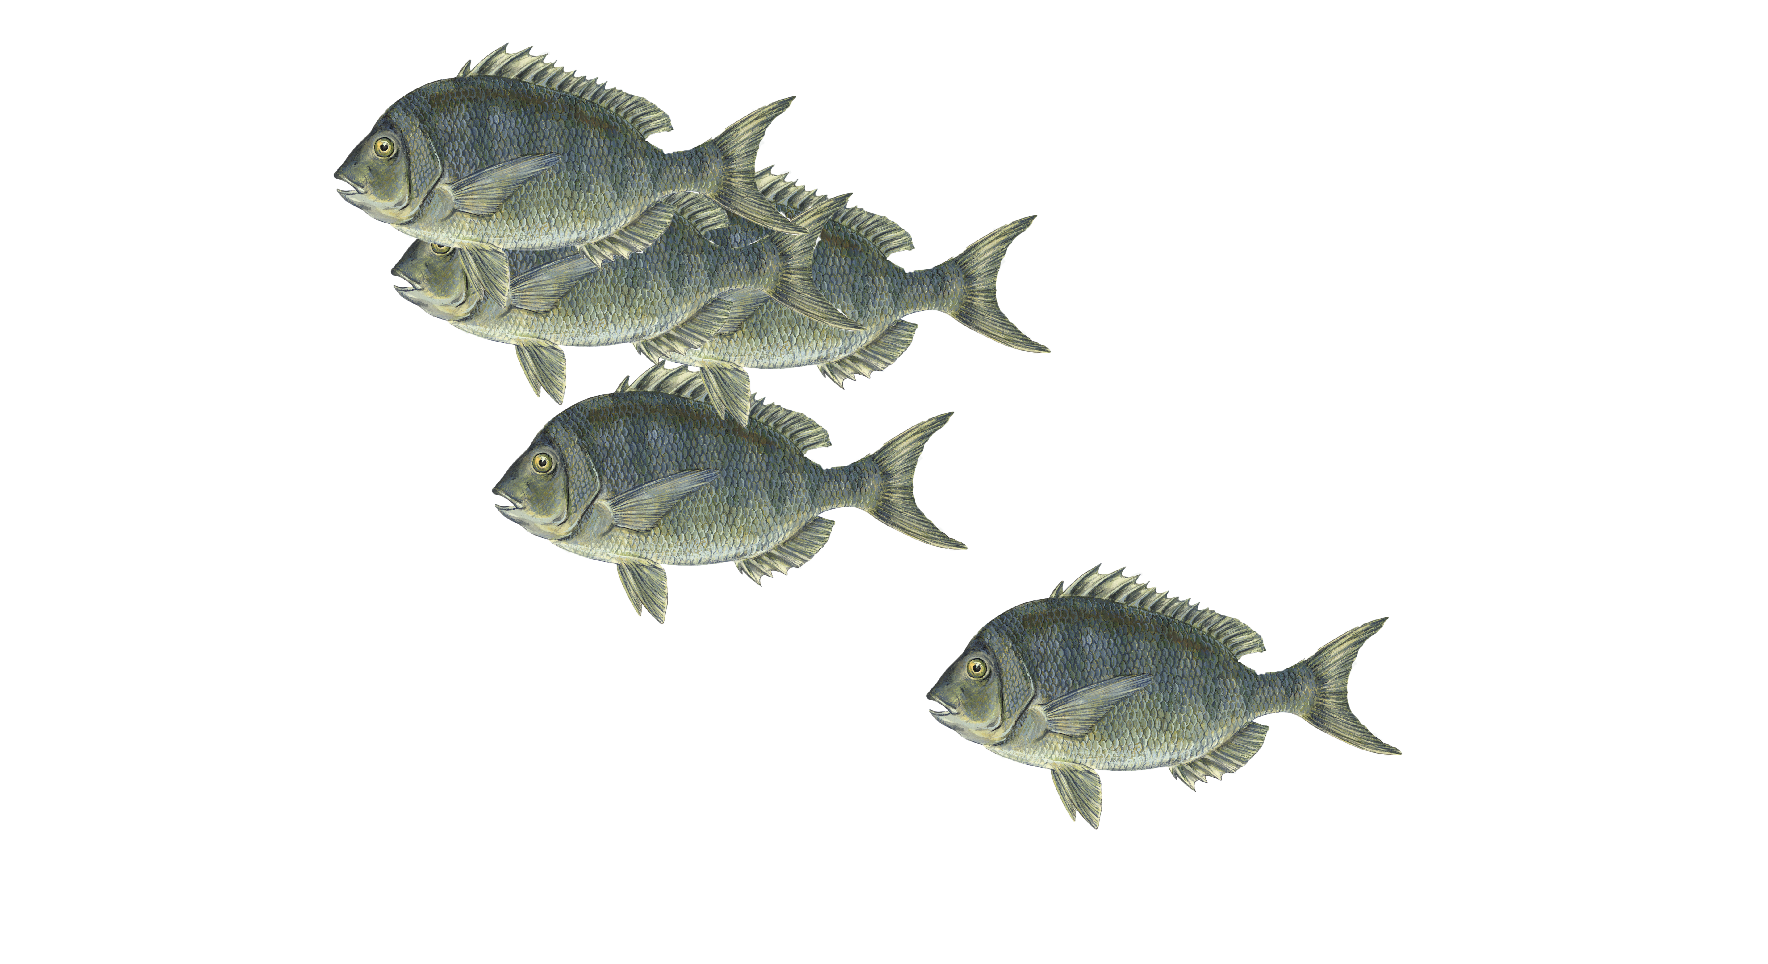

close all
% Create five fish objects
for k = 1:5
    hold on
    % Create graphics handle object describing fish
    hFish(k) = imshow(fishPic);
    
    % Assign alpha data
    hFish(k).AlphaData = alphaFish;
    
    % Define scaling factor
    sf = 0.25;
    
    % Change scaling of image on axes
    hFish(k).XData = [1,sf*hFish(k).XData(2)]+randi(500);
    hFish(k).YData = [1,sf*hFish(k).YData(2)]+randi(500);

end
hold off

**Note**: in the above code,` hold on` and `hold off` are required to ensure that all fish objects are retained on the current axes.

#### Creating your own `.png` images with transparency data

`.png` images can be created in image editing or artistic software, such as **Adobe Photoshop** or **GIMP (***https://www.gimp.org/***)**. Penn has many resources on Photoshop, including free access on campus computers. Please see the following for more information: [https://guides.library.upenn.edu/photoshop](https://guides.library.upenn.edu/photoshop)

Adobe Photoshop can also be downloaded as a [free trial](https://www.adobe.com/creativecloud.html) from Adobe. To create a `.png` file in Photoshop, use the following procedure:

- Open the image in Photoshop

- Remove image elements using the eraser, magic lasso, box selection tool, etc

- Disable the white background by clicking on the ***eye icon*** in the ***Layers*** panel – the background will turn into a checkerboard

- Crop the image to remove any unnecessary pixels

- Save the image as `.png` image.

**Example**. Create a .png file from a rock.

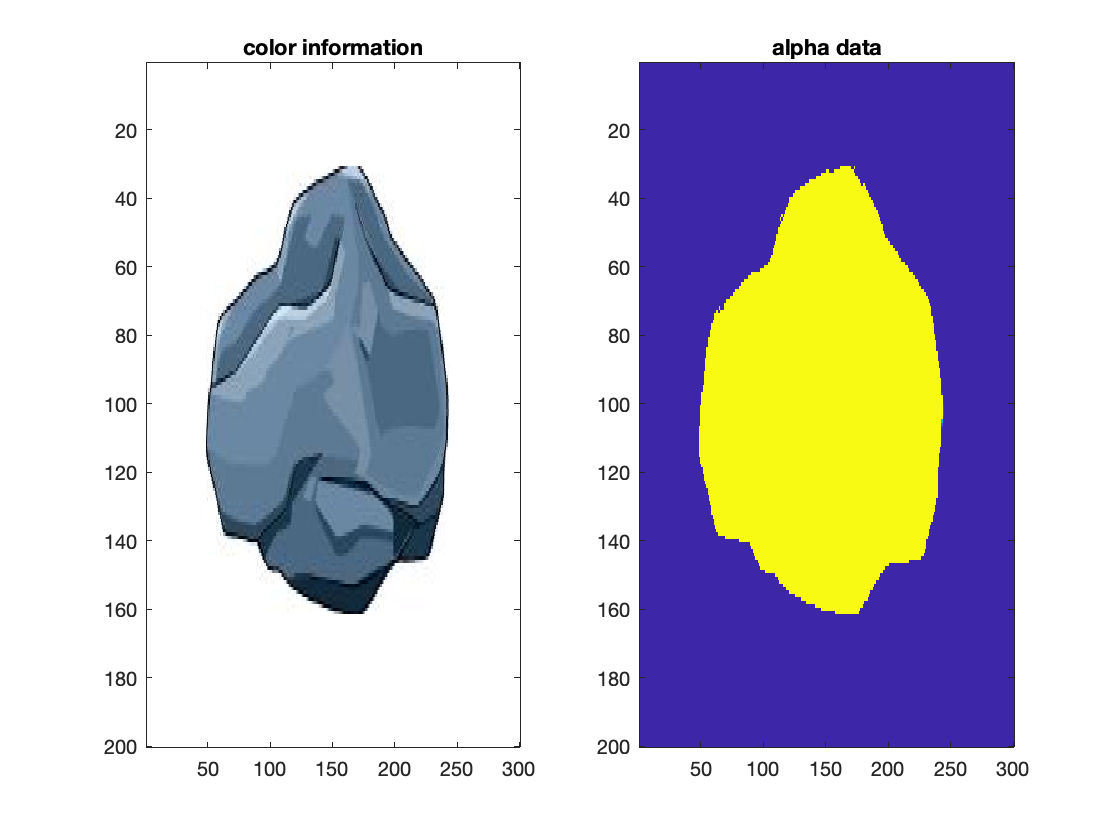

close all

% Read the fish picture and associated alpha data
[rockPic,~,alphaRock] = imread('Rock.png');

subplot(1,2,1)
image(rockPic)
title('color information')
 
subplot(1,2,2)
image(alphaRock)
title('alpha data')

#### **Object animation**

**Animating fish motion by programming the movement patterns**. Using the tools that we have used so far, we can program in fish motion.

*In this example, we:*

- Create three fish objects

- Enable each to move randomly through 200 ms time steps

- Change the background of the axes to be blue.

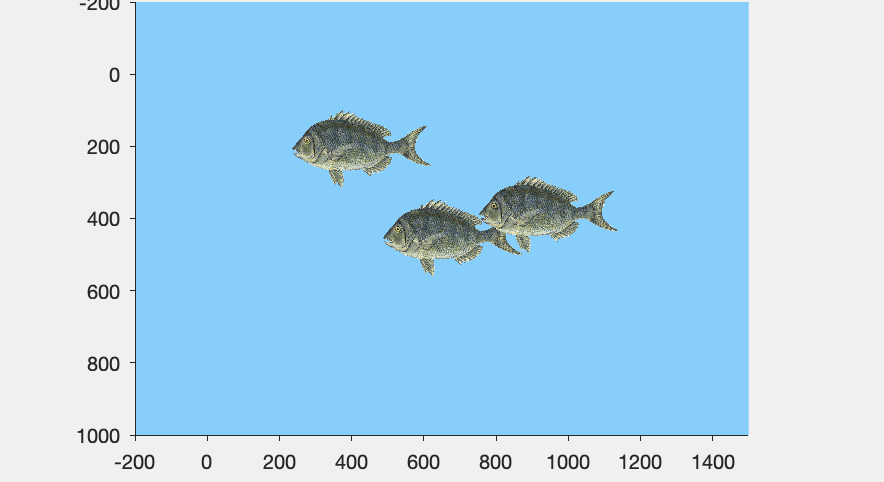

close all

% Step 1: set up figure

% Create figure and axes that are visible
h1 = figure('Visible','on');
g1 = axes;

% Create three fish objects
for k = 1:3
    hold on
    % Create graphics handle object describing fish
    hFish(k) = imshow(fishPic);
    
    % Assign alpha data
    hFish(k).AlphaData = alphaFish;
    
    % Define scaling factor
    sf = 0.25;
    
    % Change scaling of image on axes
    hFish(k).XData = [1,sf*hFish(k).XData(2)]+randi(500);
    hFish(k).YData = [1,sf*hFish(k).YData(2)]+randi(500);

end
hold off

% Ensure axes are visible
g1.Visible = 'on';

% Reduce figure window size
h1.Position(3:4) = 0.5*h1.Position(3:4);

% Change the axes background to blue
g1.Color = [135,206,250]/255;
xlim([-200,1500])
ylim([-200,1000])

% Step 2: loop through 50 simulation time steps
for m = 1:25
    % For each fish, update position
    for k = 1:3
        % Change position of image on axes
        hFish(k).XData = hFish(k).XData + randi(100) - 50;
        hFish(k).YData = hFish(k).YData + randi(100) - 50;
    end
    pause(0.1)
end

**Note**. The fish move, but it looks a little silly how they "back up" when moving to the right. One option to improve this would be to flip the image when it moves to the right.

**Animating fish motion by keyboard callback**. Using the techniques described in Topic 20 and 21, we can create a keyboard callback object to move the fish in response to arrow key keystrokes.

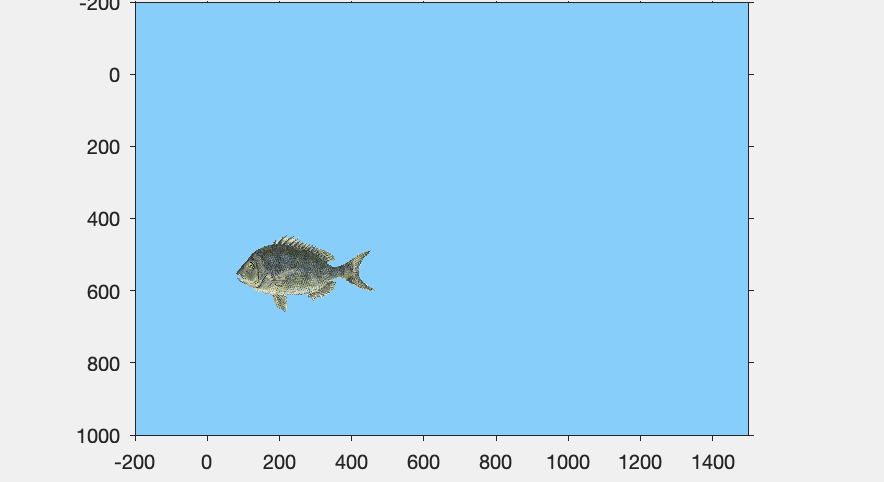

close all

% Create figure
% Create figure and axes that are visible
h1 = figure('Visible','on');
g1 = axes;

% Create data structure to store info about interface
handles = struct;
% Create field to store the current xy direction of fish
handles.moveDir = "left";
% Store the data structure as GUI data
guidata(h1,handles);

% Create fish object
% Create graphics handle object describing fish
hFish = imshow(fishPic);
% Assign alpha data
hFish.AlphaData = alphaFish;
% Define scaling factor
sf = 0.25;
% Change scaling of image on axes
hFish.XData = [1,sf*hFish.XData(2)]+randi(500);
hFish.YData = [1,sf*hFish.YData(2)]+randi(500);

% Specify additional graphical parameters
% Ensure axes are visible
g1.Visible = 'on';

% Reduce figure window size
h1.Position(3:4) = 0.5*h1.Position(3:4);

% Change the axes background to blue
g1.Color = [135,206,250]/255;
xlim([-200,1500])
ylim([-200,1000])

% Assign key press function
h1.KeyPressFcn = {@DoWhenKeyIsPressed,hFish};

#### **Animation with timer objects**

Events can be timed/initiated at specific intervals using [`tic`](https://www.mathworks.com/help/matlab/ref/tic.html)[/](https://www.mathworks.com/help/matlab/ref/tic.html)[`toc`](https://www.mathworks.com/help/matlab/ref/tic.html), [`clock`](https://www.mathworks.com/help/matlab/ref/clock.html), or **timer objects**. 

- `tic`/`toc `and `clock` are effective when code naturally involves loops, but timer objects can initiate events even without a loop

- [Timer objects](https://www.mathworks.com/help/matlab/matlab_prog/use-a-matlab-timer-object.html) are not loops, run independently "in the background", and allow for more precise timing/execution of events.

- Just like when creating mouse and keyboard callbacks, timers utilize callbacks to perform actions

**Example. **Print `Hello person!` to the command line 5 times after a 2 second delay and in 3 second intervals using a timer object.

% Set up the timer object t.
t = timer('TimerFcn', @sayIt, 'StartFcn', @startItUp, 'StopFcn', @stopIt, 'ExecutionMode', 'fixedRate', 'StartDelay', 2, 'Period', 3, 'TasksToExecute', 5);



% start timer
start(t)

The timer associates local functions (subfunctions) with the start (`'``StartFcn``'`), firing (`'``TimerFcn``'`), and stop (`'``StopFcn``'`) of the timer

- In the above, the following function is executed **at timer start**:

- In the above, the following function is the "TimerFcn" who is called based on the commands in the timer

- In the above, the following function is executed **at timer end**. Note: the timer is deleted at the end.

**Note****: **as with all objects, the fields can be modified using dot notation.

**IMPORTANT: **ALWAYS STOP AND DELETE TIMERS WHEN DONE WITH THEM - NOT DOING SO CAN LEAD TO A LOT OF TIMERS LEFT RUNNING IN THE BACKGROUND AND SUCKING COMPUTER RESOURCES 

Specific timers can be stopped by reference to their handles

All timers can be stopped and deleted by specifying

#### **Example problem: rock simulator**

Animate a sequence of falling rocks in water based on a **timer object**. 

*This code should:*

- Create a timer that makes a rock fall three times, with one rock falling every 4 seconds

- Create one rock object that falls multiple times

- Use material properties where possible to ensure that the simulation is physically reasonable

**Step 1: Plan, pseudocode, and prepare**. Write down what we know. Assume the stone is **granite** and treat it as a sphere of radius **150 m**.

*Values that we know:*

- Density of granite:  $\rho =2,670\;\frac{\textrm{kg}}{m^3 }$

- Density of water: $\rho_w =1,000\;\frac{\textrm{kg}}{m^3 }$

- Viscosity of water:  $\eta ={10}^{-3} \;\textrm{Pa}\cdot s$

- Radius of rock: $a=150\;m$

*Creating the differential equation:*

From our knowledge of **physics**, we know that the force exerted on an object by gravity (and including buoyancy) is given by the following equation, where $g$ is the acceleration due to gravity and $V$ is the volume of the rock (assumed to be a sphere).

            
$$F_g \left(t\right)=-\left(\rho -\rho_w \right)\textrm{gV}=-\frac{4\pi }{3}a^3 \left(\rho -\rho_w \right)g$$


Last Tuesday, we used **Stokes's law** to describe the drag force induced by a liquid on a sphere. We will use this relationship again here:

            
$$F_{\textrm{drag}} \left(t\right)=-6\pi a\eta v\left(t\right)=-6\pi a\eta \frac{\textrm{dx}}{\textrm{dt}}$$


From **Newton's second law of motion**, we can thus relate all forces acting on the object:

            
$$\textrm{ma}=m\frac{d^2 x}{{\textrm{dt}}^2 }=\rho \frac{4}{3}\pi a^3 \frac{d^2 x}{{\textrm{dt}}^2 }=\sum_i F_i \left(t\right)$$


Simplifying this differential equation:

            
$$\begin{array}{l}
\rho \frac{4}{3}\pi a^3 \frac{d^2 x}{{\textrm{dt}}^2 }\;+6\pi a\eta \frac{\textrm{dx}}{\textrm{dt}}+\frac{4\pi }{3}a^3 \left(\rho -\rho_w \right)g=0\\
\frac{d^2 x}{{\textrm{dt}}^2 }\;+\frac{6\eta }{\rho \frac{4}{3}a^2 }\frac{\textrm{dx}}{\textrm{dt}}+\frac{\left(\rho -\rho_w \right)g}{\rho }=0
\end{array}$$


Or, by definining and substituting variables $b$ and $c$:

            
$$\begin{array}{l}
\frac{d^2 x}{{\textrm{dt}}^2 }\;+b\frac{\textrm{dx}}{\textrm{dt}}+c=0\\
b=\frac{6\eta }{\rho \frac{4}{3}a^2 }\\
c=\frac{\left(\rho -\rho_w \right)g}{\rho }
\end{array}$$


**Step 2: Create a "base" visualization (that does not include the physics)**

This code should incorporate a timer and timer function that drops a rock every four seconds. The timer callback function is given here:

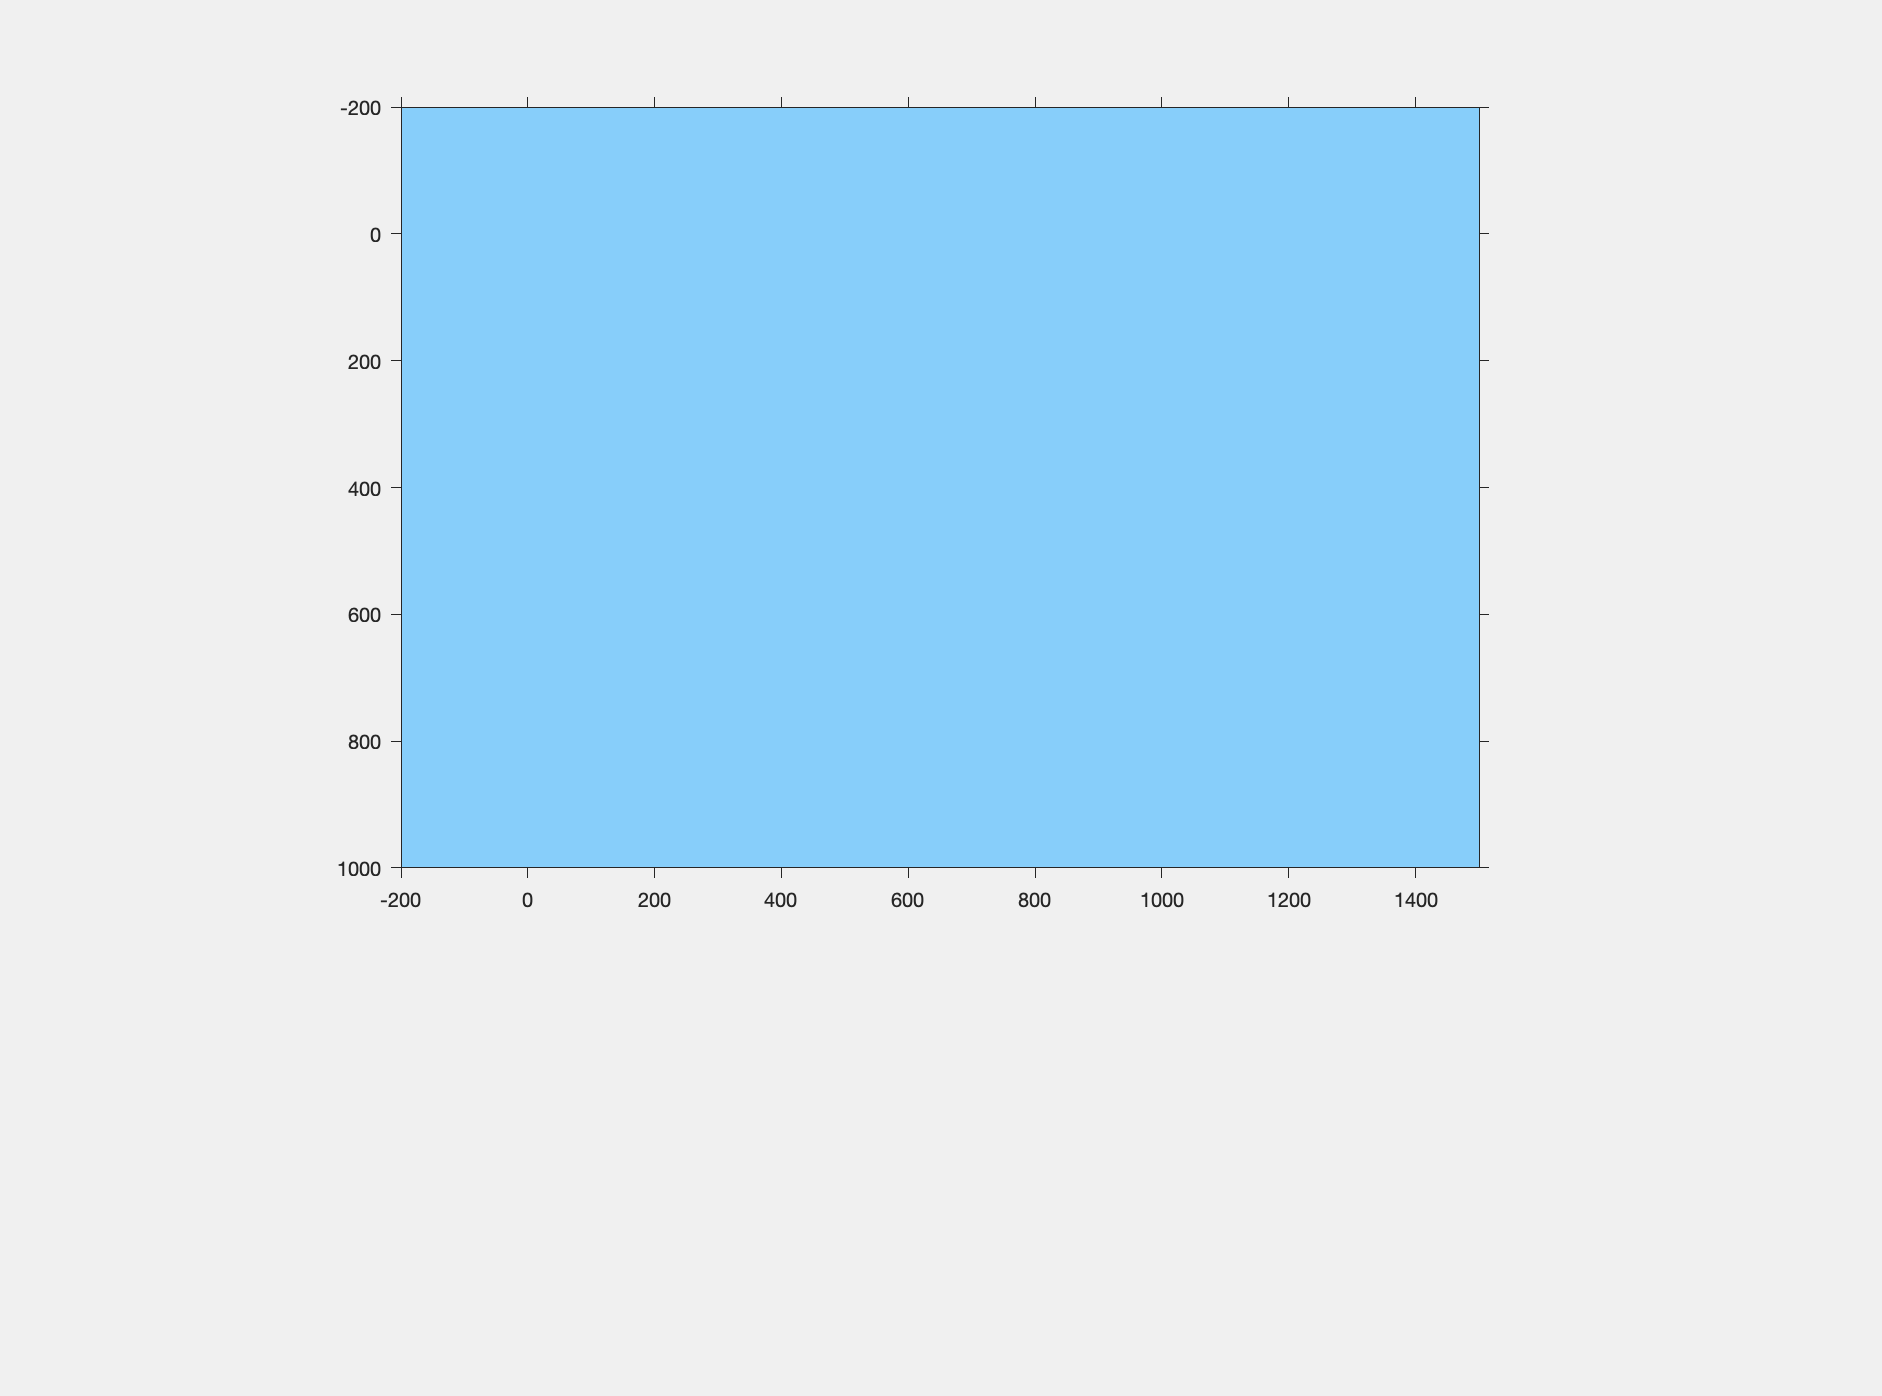

close all

% Create figure
% Create figure and axes that are visible
h2 = figure('Visible','on');
g2 = axes;

% Create rock object using the previously loaded rock
% Create graphics handle object describing rock
hRock = imshow(rockPic);
hRock.Visible = 'off';
% Assign alpha daya
hRock.AlphaData = alphaRock;
% Store XY dimmensions of rock
hRockSize = [hRock.XData(2), hRock.YData(2)];

% Ensure axes are visible
g2.Visible = 'on';

% Change the axes background to blue 
g2.Color = [135,206,250]/255;
xlim([-200,1500])
ylim([-200,1000])
h2.Position = [672,238,941,698];

**Note**: the above code uses the the same `stopIt` function as above to ensure that the timer is deleted once it runs to completion

**Step 3: Incorporate the physics**

To solve using `ode45`, a higher order differential equation must be rewritten as a set of differential equations. Here, the differential equation is:

            
$$\frac{d^2 x}{{\textrm{dt}}^2 }\;+b\frac{\textrm{dx}}{\textrm{dt}}+c=0$$


Defining new variables:

            
$$\begin{array}{l}
x=y_1 \\
\frac{\textrm{dx}}{\textrm{dt}}=\;\frac{dy_1 }{\textrm{dt}}=y_2 \\
\frac{d{\mathrm{y}}_2 }{\textrm{dt}}\;=-by_2 -c
\end{array}$$


Thus, we can use the following function to represent the system of ODEs:

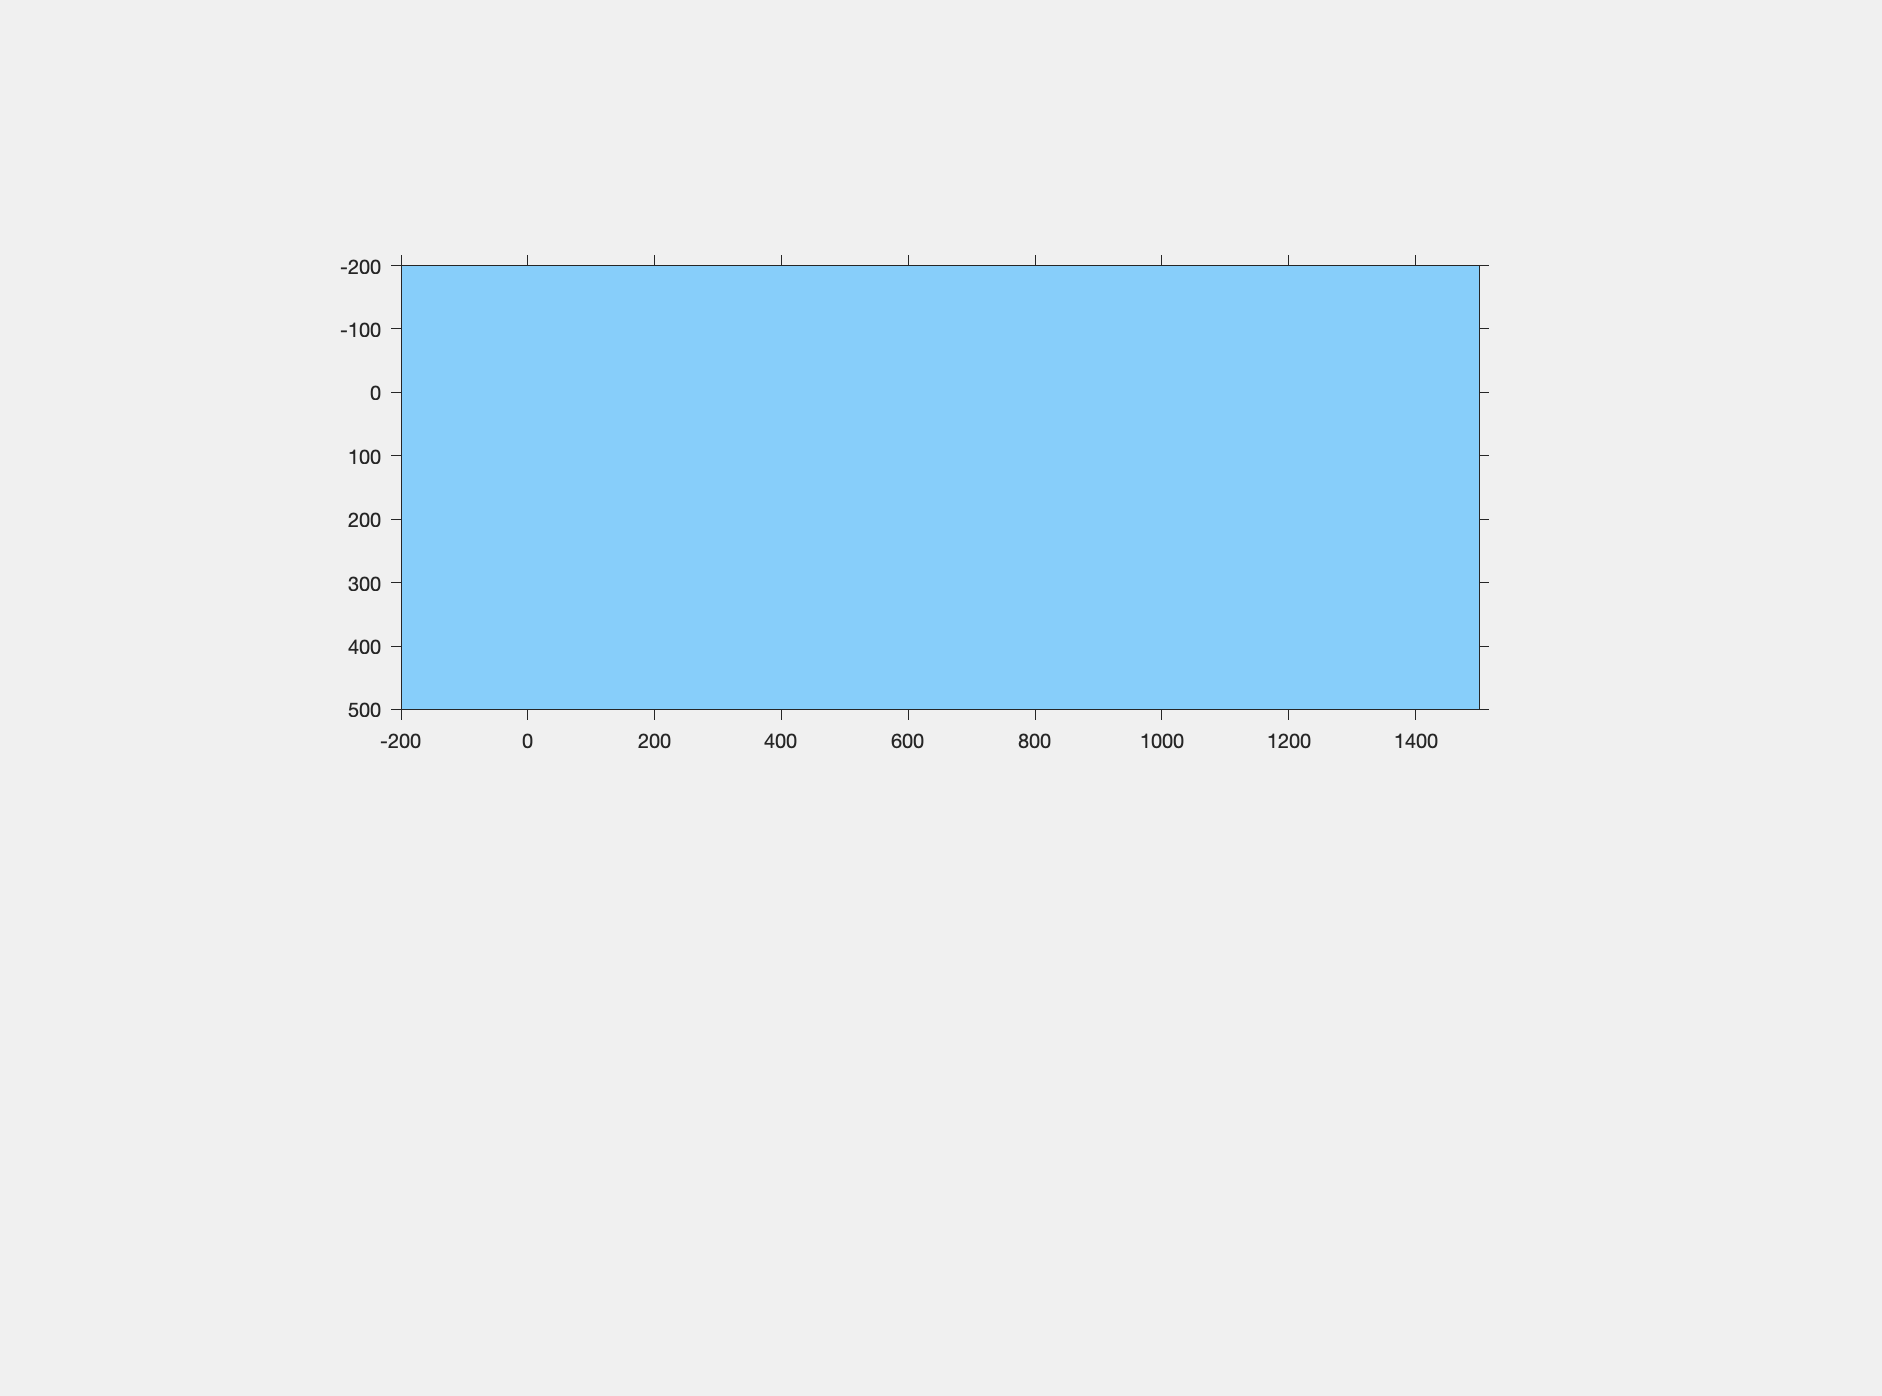

close all

% Create figure
% Create figure and axes that are visible
h2 = figure('Visible','on');
g2 = axes;

% Physical parameters
rho_g = 2670;
rho_w = 1000;
eta = 10^-3;
a = 150;
g = 9.81;

% Constants
b = 6*eta/(rho_g*4/3*a^2);
c = (rho_g - rho_w)*g/rho_g;
% Estimate time to stop ODE calculation
t_end = 5*sqrt(1000/c);

%Solve ODE
[t,out] = ode45(@rockODE, 0:0.05:t_end, [0,0], [],b,c);
out = -out;
y = out(out(:,1)<600);
t = t(out(:,1)<600);

% Create rock object using the previously loaded rock
% Create graphics handle object describing rock
hRock = imshow(rockPic);
hRock.Visible = 'off';

% Assign alpha data
hRock.AlphaData = alphaRock;
% Store XY dimmensions of rock
hRockSize = [hRock.XData(2),hRock.YData(2)];

% Ensure axes are visible
g2.Visible = 'on';

% Change the axes background to blue
g2.Color = [135, 206, 250]/255;
xlim([-200,1500])
ylim([-200,500])
h2.Position = [672,238,941,698];

#### Example problem: drag and drop

A useful feature of interfaces in the capability for "drag-and-drop" user interactions. Produce a script that enables the user to "drag-and-drop" circles on an interface. 

*This script requires mouse callbacks to perform the following operations:*

- Left click within the boundary of the nearast marker to grab it

- Use the `'WindowButtonMotionFcn'` call back to move it

- Release the mouse button releases control of the marker

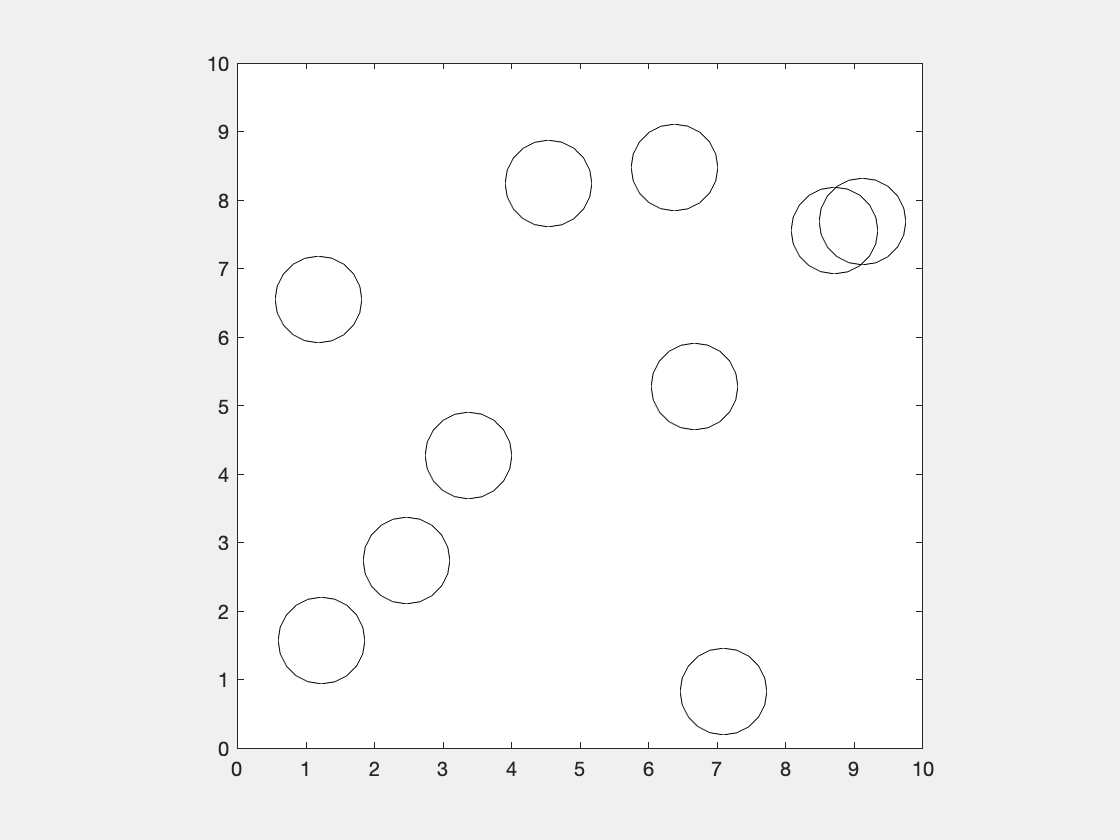

close all

% Establish the figure and the button down/up and motion
% callbacks.
h1 = figure('Visible','on');

% The diameter of the markers.
D = 1;

% 'ind' will be used to track the index of the marker that is to
% be moved when a mouse movement is detected. An empty set
% indicates that no index has been selected.
handles.ind = [];

% Store guidata
guidata(h1,handles);

% Initialize the center locations of 10 markers.
x = (10-D)*rand(1,10)+D/2;
y = (10-D)*rand(1,10)+D/2;

% Plot the markers.
p = plot(x,y,'ko');

% Adjust the axis scaling so that the radius of the markers is
% scaled to the size of the axes.
axis equal
axis([0 10 0 10])
ax = gca;
ax.Units = 'points';
p.MarkerSize = D/diff(xlim)*ax.Position(3);

% Declare callback functions
h1.WindowButtonDownFcn = {@pick,D,p};
h1.WindowButtonMotionFcn = {@move,p};
h1.WindowButtonUpFcn = @place;

**Functions for Topic 25 stored here:**

- **Example: GUI with counter**

function subtractVal(hObj,~,hedit,h1)
    % Subtract 1 from the counter value
    handles = guidata(h1);
    cVal = handles.cVal - 1;
    
    set(hedit,'String',cVal)
    guidata(handles,h1);
end

function addVal(hObj,~,hedit,h1)
    % Add 1 to the counter value
    handles = guidata(h1);
    cVal = handles.cVal + 1;
   
    set(hedit,'String',cVal)
    guidata(handles,h1);
end

- **Example: animating a fish**

function DoWhenKeyIsPressed(h1,eventdata,hFish)
    % Utilizes keypresses to move the x/y coordinates of the
    % ball or closes the figure.
    
    % Load GUI data
    % Create field to store the current xy direction of fish
    handles = guidata(h1);
    
    % Movement increment
    inc = 10; 

    % Move up
    if strcmp(eventdata.Key,'uparrow')
        hFish.YData = hFish.YData - inc;
        
    % Move down
    elseif strcmp(eventdata.Key,'downarrow')
        hFish.YData = hFish.YData + inc;
        
    % Move left
    elseif strcmp(eventdata.Key,'leftarrow') 
        % If the current direction is set to move left
        if handles.moveDir == "left"
            hFish.XData = hFish.XData - inc;
        % Otherwise, flip the orientation of the fish
        else
            hFish.XData = fliplr(hFish.XData) - inc;
            handles.moveDir = "left";
        end
        
    % Move right
    elseif strcmp(eventdata.Key,'rightarrow')   
        % If the current direction is set to move left
        if handles.moveDir == "right"
            hFish.XData = hFish.XData + inc;
        % Otherwise, flip the orientation of the fish
        else
            hFish.XData = fliplr(hFish.XData) + inc;
            handles.moveDir = "right";
        end
        
    % Close figure
    elseif strcmp(eventdata.Key,'q')  
        close()
    % Display invalid keystroke
    else
        disp('Key not mapped')
    end
    
    % Store the data structure as GUI data
    guidata(h1,handles);
end

- **Example: timer function 1**

function startItUp(~,~)
    % Timer StartFcn callback.
    disp('A timer has been started.')
    disp('It will wait 2 seconds to fire the first time...')
    disp('and then it will fire every 3 seconds for 5 rounds!')
end

function sayIt(~,~)
    % Timer fxn callback.
    disp('Hello person!')
end

function stopIt(t,~)
    % Timer StopFcn callback.
    disp('The timer ''StopFcn'' just executed.')
    disp(['It utilizes the first input of the callback, '...
        'the handle of the timer, to stop the timer.'])
    disp('Always delete timers after you are done using them.')
    
    delete(t)
end

- **Example: falling rock**

function dropRock(~,~,hRock,hRockSize)
    % Timer function that is called everytime the rock should be dropped 
    
    % Reset the rock's initial position to be above the water line
    hRock.XData = [1,hRockSize(1)] + randi(1000);
    hRock.YData = [-hRockSize(2),-1];
    
    % Ensure rock is visible
    hRock.Visible = 'on';
    
    % Loop through time steps and move the rock down by some known amount
    % of time
    for k = 1:50
        hRock.YData = hRock.YData + 100;
        pause(0.1)
    end
end

function dYdt = rockODE(t,y,b,c)

    dYdt = zeros(2,1);
    dYdt(1) = y(2); % y(1) = x
    dYdt(2) = -b*y(2) - c; % z(2) = dy/dt

end

function dropRock_2(~,~,hRock,hRockSize,y_data)
    % Timer function that is called everytime the rock should be dropped 
    
    % Reset the rock's initial position to be above the water line
    hRock.XData = [1,hRockSize(1)] + randi(1000);
    hRock.YData = [-hRockSize(2),-1];
    
    initialPos = hRock.YData;
    
    % Ensure rock is visible
    hRock.Visible = 'on';
    
    % Loop through time steps and move the rock down by some known amount
    % of time
    for k = 1:length(y_data)
        hRock.YData = initialPos + y_data(k);
        pause(0.05)
    end
end

- **Example: drag and drop**

function pick(h1,~,D,p)
    % Mouse button down callback. Determines if the mouse was
    % clicked within the limits of a marker and, if so, takes
    % control of the marker.
    
    handles = guidata(h1);
    
    % Get the location of the mouse.
    pos = get(gca,'CurrentPoint');
    xMouse = pos(1,1);
    yMouse = pos(1,2);
    
    % Determine which marker centerpoint the mouse is closest
    % to and record the vector index number.
    [distance,minInd] = min(sqrt((xMouse-p.XData).^2+(yMouse-p.YData).^2));
    
    % If the mouse is within a radius of the marker, then
    % take control of the x/y marker centerpoint index and
    % calculate the difference between the centerpoint of the
    % marker and where the user actually clicked.
    if distance <= D/2
        handles.ind = minInd;
    end
    
    guidata(h1,handles);

end

function move(h1,~,p)
    % Mouse motion callback. Moves the marker centerpoint
    % held in x/y index 'ind' if 'ind' is not an empty set.
    % Updates visuals accordingly.
    
    handles = guidata(h1);
    ind = handles.ind;
    
    % Get the location of the mouse.
    pos = get(gca,'CurrentPoint');
    xMouse = pos(1,1);
    yMouse = pos(1,2);
    
    % Update the x/y centerpoint corresponding to 'ind'.
    p.XData(ind) = xMouse;
    p.YData(ind) = yMouse;
    drawnow
end

function place(h1,~)
    % Mouse up callback. Release control of 'ind'.
    handles = guidata(h1);
    handles.ind = [];
    guidata(h1,handles);
end